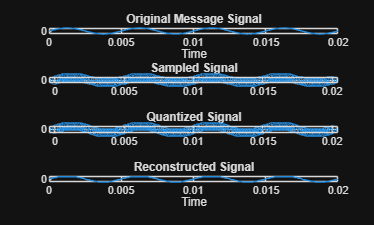

clc;
clear;
close all;

%% Parameters
fs = 8000;           % Sampling frequency
fm = 200;            % Message frequency
t = 0:1/fs:0.02;     % Time vector
n = 3;               % Number of bits
L = 2^n;             % Quantization levels

%% Message Signal
m = sin(2*pi*fm*t);

%% Sampling
sampled = m;

%% Quantization
xmin = min(sampled);
xmax = max(sampled);
delta = (xmax - xmin)/L;

q = round((sampled - xmin)/delta);
q(q > L-1) = L-1;

quantized = xmin + q*delta;

%% Encoding
encoded = de2bi(q,n,'left-msb');

%% Decoding
decoded = bi2de(encoded,'left-msb');

%% Reconstruction
reconstructed = xmin + decoded*delta;

%% Plotting
figure

subplot(4,1,1)
plot(t,m)
title('Original Message Signal')
xlabel('Time')
ylabel('Amplitude')

subplot(4,1,2)
stem(t,sampled)
title('Sampled Signal')

subplot(4,1,3)
stem(t,quantized)
title('Quantized Signal')

subplot(4,1,4)
plot(t,reconstructed)
title('Reconstructed Signal')
xlabel('Time')
ylabel('Amplitude')